# Assess Stability of Inverter-Based Resources (IBRs) using Admittance Scan Technique

## Introduction   

This project investigates the use of admittance scanning to detect oscillatory instability in power networks with a high presence of inverter-based resources (IBRs). Inverters integrate renewable sources, like solar plants, wind generators, and battery energy storage systems (BESS), into the power network. These inverters have fast-acting controllers and limited short-circuit capacity [1]. IBRs replace conventional synchronous generators, reducing grid strength, which makes it challenging to maintain a stable system.

IBRs can destabilize grid voltage because of interactions between the IBR feedback controller and the equivalent grid. These interactions cause oscillations in the three-phase voltages and currents, which can cause the protection system to trip the renewable plant.

### Grid Strength Assessment

The short-circuit ratio (SCR) is a standard metric for assessing grid strength at the POI. SCR is the ratio of the short-circuit capacity assuming a three-phase fault to the the nominal power of the connected IBR. A high SCR indicates a strong grid, which can accommodate new IBRs without causing any instability.

The utility of SCR is limited because it is a static index that only considers impedance at the fundamental frequency. The SCR cannot capture oscillatory instabilities due to resonance at wider interaction frequencies [1]. The fast dynamics and low overloading capacity of power electronic converters can cause wide band dynamic and transient stability problems, including resonance, and control interactions between IBRs and the grid. The oscillations in three-phase voltages and current can occur over a wide range of frequencies. You can assess these oscillatory instability phenomena in IBRs, using admittance scanning. You estimate the effective admittance of the IBR and the grid, at the point of interconnection (POI), over a range of frequencies.

## IBR Control 

You can control IBRs using grid-following (GFL) or grid-forming (GFM) controllers. A GFL controller makes the inverter behave like a controlled current sources in parallel with an impedance. A GFM controller makes the inverter behave like a controlled voltage source behind an impedance. Most grid-connected IBRs use GFL control. You can integrate additional control functions into the inverter controller so that the inverter performs in accordance to grid codes under various operating conditions: 

- Fault-ride through

- Virtual inertia

- Current limiting control

- Virtual impedance control

This figure shows the small-signal representation of a GFM inverter.

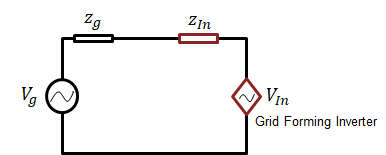 

This figure shows the small-signal representation of a GFL inverter.

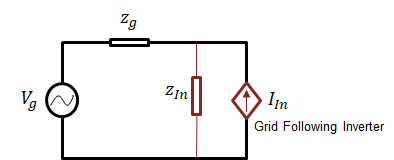

## Admittance Scan

You perform small-signal stability analysis of IBR dominated power networks by studying the linearized system under a steady-state condition. This approach needs an open-box models of the IBRs, synchronous generators, and the power network. However, you cannot represent IBRs adequately using generic models because IBRs have complex dynamic behavior with a large number of nonlinearities in the control loop. Moreover, many manufacturers only supply the black-box models of IBRs. Thus, the detailed models are not available for analysis [1].

Admittance scanning is a data driven method of stability assessment, which uses only measurements made at the POI of the IBR, to determine the frequency vs. admittance characteristics of the grid-connected system. These characteristics are valid for the operating condition over which you estimate the admittance [2].

The admittance identification process is based on injecting small voltage or current perturbations in the network at the POI, and measuring the deviation in current or voltage, within the frequency range of interest. In this project, you can obtain the admittance scan using a wide band series voltage injection at different frequencies and measure the variation in currents at the POI.

This figure shows an IBR connected to the grid through a power network. $Y_N$ the network admittance and$Y_A$ represents the IBR equivalent admittance. 

You can connect a series voltage injection source is between the IBR and the network at the POI, this source injects three-phase voltage perturbations, ${\Delta v}_{\textrm{abc}}$, at the POI and you can measure the corresponding current perturbations, ${\Delta i}_{\textrm{abc}}$. 

Using these perturbed voltages and currents the admittance of the system at the POI is estimated. 

                                                                                         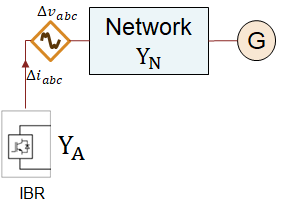                  

  This figure shows the equivalent feedback control mechanism  between the IBR and the grid, using the IBR and the network admittance.

                                                                          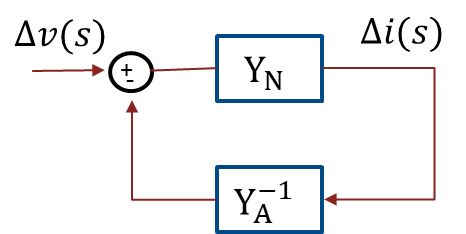

You calculate the admittance transfer function between the perturbed current and voltage using this equation :    $\frac{\Delta i}{\Delta v}=\frac{Y_N }{\left(1+Y_N Y_A^{-1} \right)}={\left(1+Y_N Y_A^{-1} \right)}^{-1} Y_N$. The poles of this admittance transfer function equal the state-space eigenvalues, such that all elements contain dynamics of the system [1].                                                

You can measure the admittance at the POI  in the abc frame, the d-q frame, or in the sequence frame. This project uses measurement and estimation of admittance in the d-q frame. The system of equations depicting the relationship among the admittance, perturbed voltages, and currents along the d and Q axis are given below.

#### 
$$\left\lbrack \begin{array}{cc}
Y_{\textrm{dd}}  & Y_{\textrm{dq}} \\
Y_{\textrm{qd}}  & Y_{\textrm{qq}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\Delta V}_d \\
{\Delta V}_q 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\Delta i}_d \\
{\Delta i}_q 
\end{array}\right\rbrack$$


After you inject voltage perturbations at the POI, you transform the perturbations in the currents at the POI into the corresponding d and q components. Then you apply a fast Fourier transform  on the perturbed voltages and currents.

To obtain the admittance transfer function, you use the vector fitting transfer function estimation algorithm, provided with System Identification Toolbox(TM). The algorithm uses the input voltage perturbation data and the

measured current response data for a given time window. The window length of the data for the estimation is the time for which you apply the  disturbance. 

For a fixed sampling rate, the time window must be long enough so that you have enough data points to capture the impedance spectra accurately. The time window must also be short enough to avoid increasing impedance calculation times. You can identify the d and q axis admittance sequentially, by injecting the voltage disturbance first on the d-component only and then along the q-component only.

This figure shows the process of estimating the admittance spectrum using series voltage injection.

                             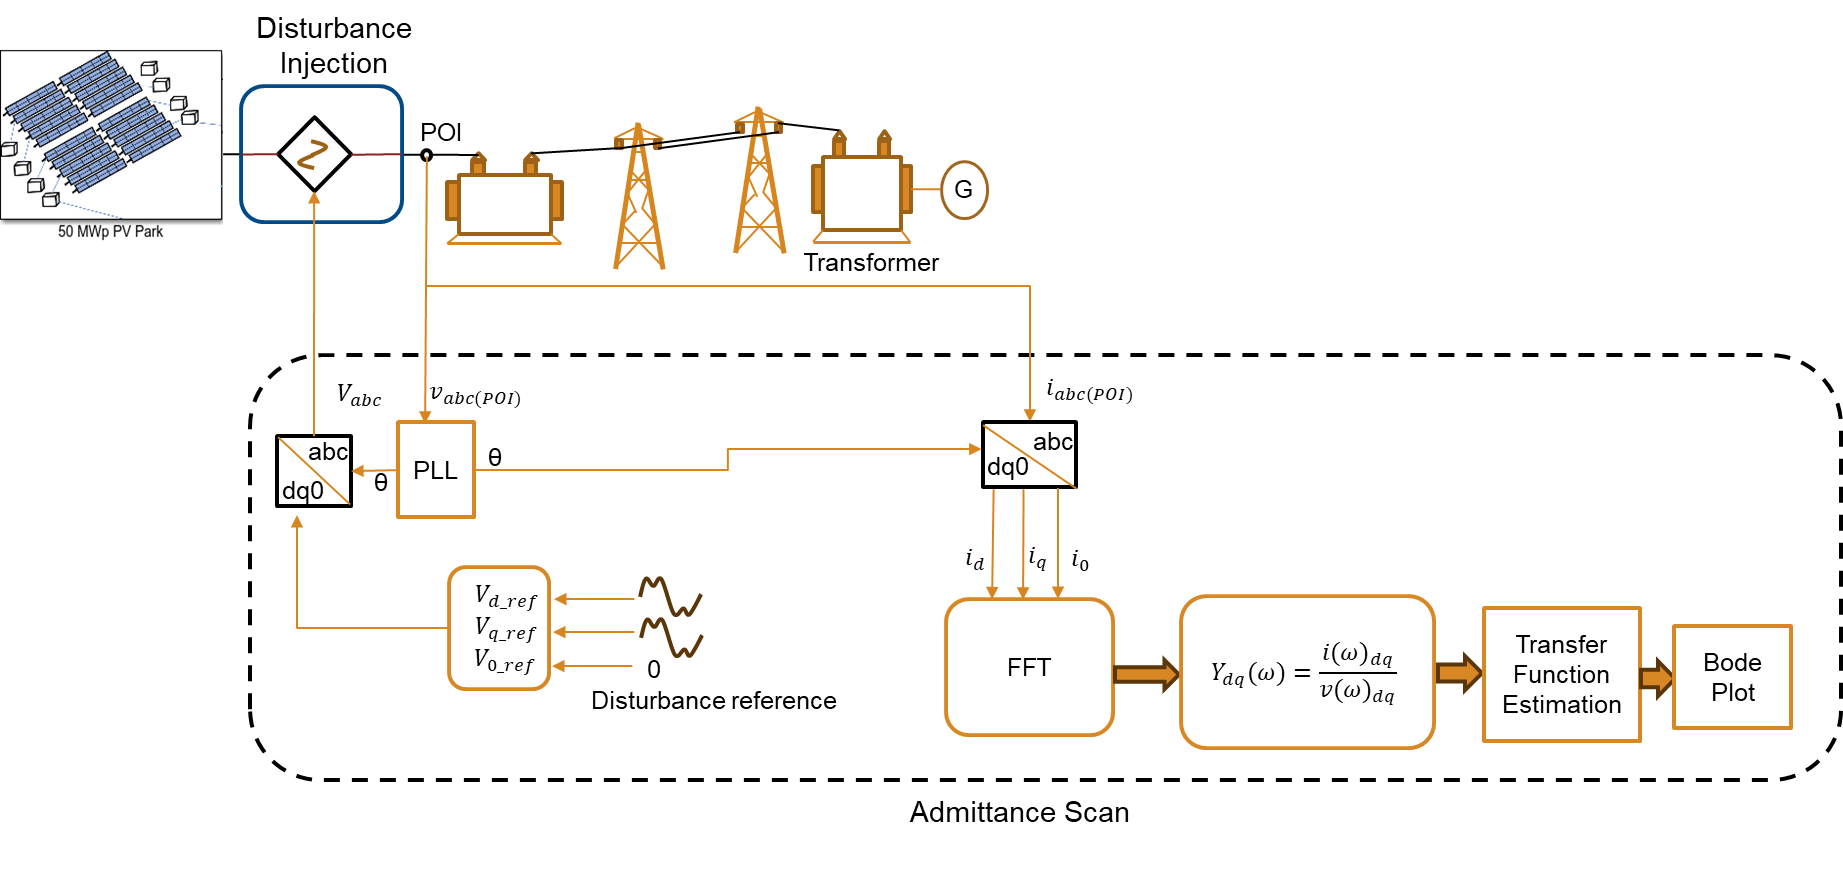

### PRBS Voltage Disturbance Injection

The Admittance Scan block is a custom component that injects voltage disturbances in the form of a pseudo random binary sequence (PRBS). You can set the magnitude of the PRBS signal that you inject into each axis by setting the PRBS Magnitude Along Vd (PU) and PRBS Magnitude Along Vq (PU) parameters.

The Admittance Scan block has a phase-locked loop (PLL) that tracks the steady-state grid frequency and phase which converts the measured voltages and currents into their respective d and q components. The block also uses the PLL phase angle to generate series voltage perturbations. The block converts the reference d and q axis perturbation voltages into their corresponding abc- phase voltages for series injection.

The Admittance Scan block has a phase-locked loop (PLL) that tracks the steady-state grid frequency and phase which converts the measured voltages and currents into their respective d and q components. The block also uses the PLL phase angle to generate series voltage perturbations. The block converts the reference d and q axis perturbation voltages into their corresponding abc- phase voltages for series injection.

The Admittance Scan block performs the FFT on the voltage and current measurements and generates the frequency response data (FRD).  Then, after obtaining the FRD, you can use the `admittancescanPRBS(Vd,Vq,Vdc,f,data,modelorder,'Y') `function to obtain the admittance spectrum of the system at the POI along the D axis and Q axis.    

The `admittancescanPRBS(Vd,Vq,Vdc,f,data,modelorder,'Y')` function takes the magnitude of the injected voltage disturbance along the DQ axis, and DC- side as `Vd ,Vq, `and`, Vdc`. The disturbance frequency vector is `f` in Hz, the FRD, `data`, and the model order which you need to provide as the fourth input. You can use an optional argument Y/N to plot the frequency response.

                                                                                                        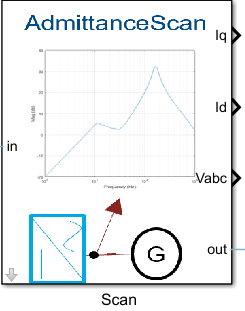             

           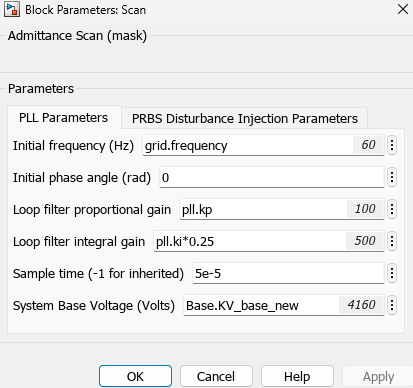                                                 

## Results and Verification

In this project you use the 'AdmittanceScanPRBS.slx' model to test the Admittance Scan block. This model consists of renewable plant which you can be configured as a PV park with a BESS, or a wind farm with multiple wind  generators. A transformer connects the renewable plant to a transmission network. You consider two renewable plant models. One model has a wind farm and the other model has a solar plant with BESS.

This figure shows the simulation model used for validating the admittance scan results.

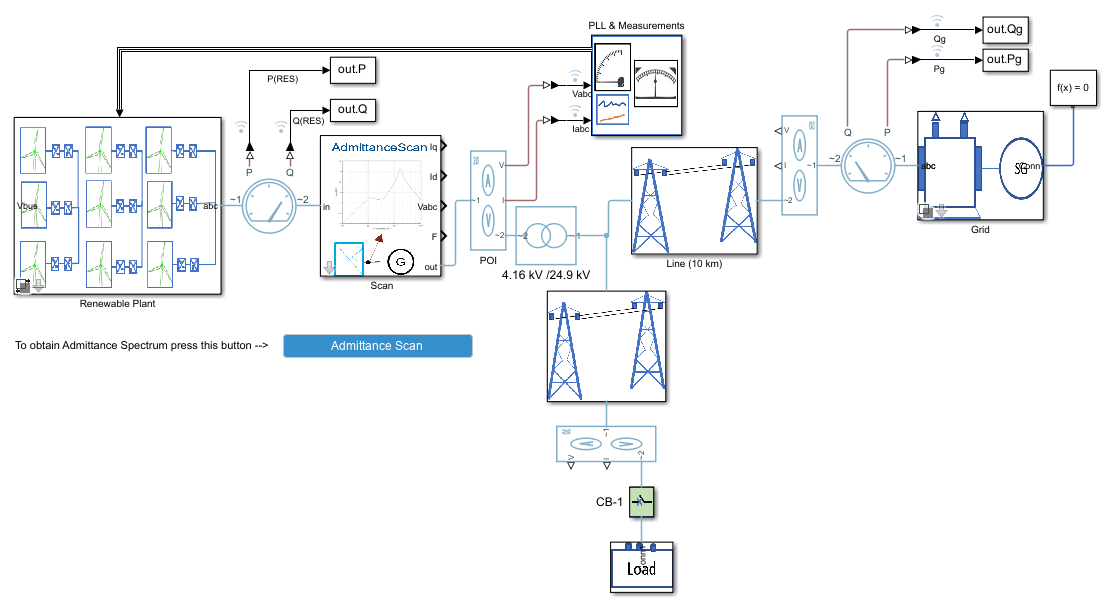

### Wind Farm Integration

The turbines connect to type-4 wind generators, each wind turbine produces a maximum power of 6.2 MW at a rated wind speed of 12 m/sec. The GFL wind turbine generators operate at their maximum power point (MPP) using a PLL -based controller.

 Use this model to study the effect of wind power penetration on the small signal stability of the system by varying the number of wind turbine generators in the wind farm. 

The Admittance Scan block is connected in series between the wind farm and the grid at the POI.

#### Case 1.1: Wind Farm with 5 GFL Wind generator and the Grid Modelled with Voltage Source

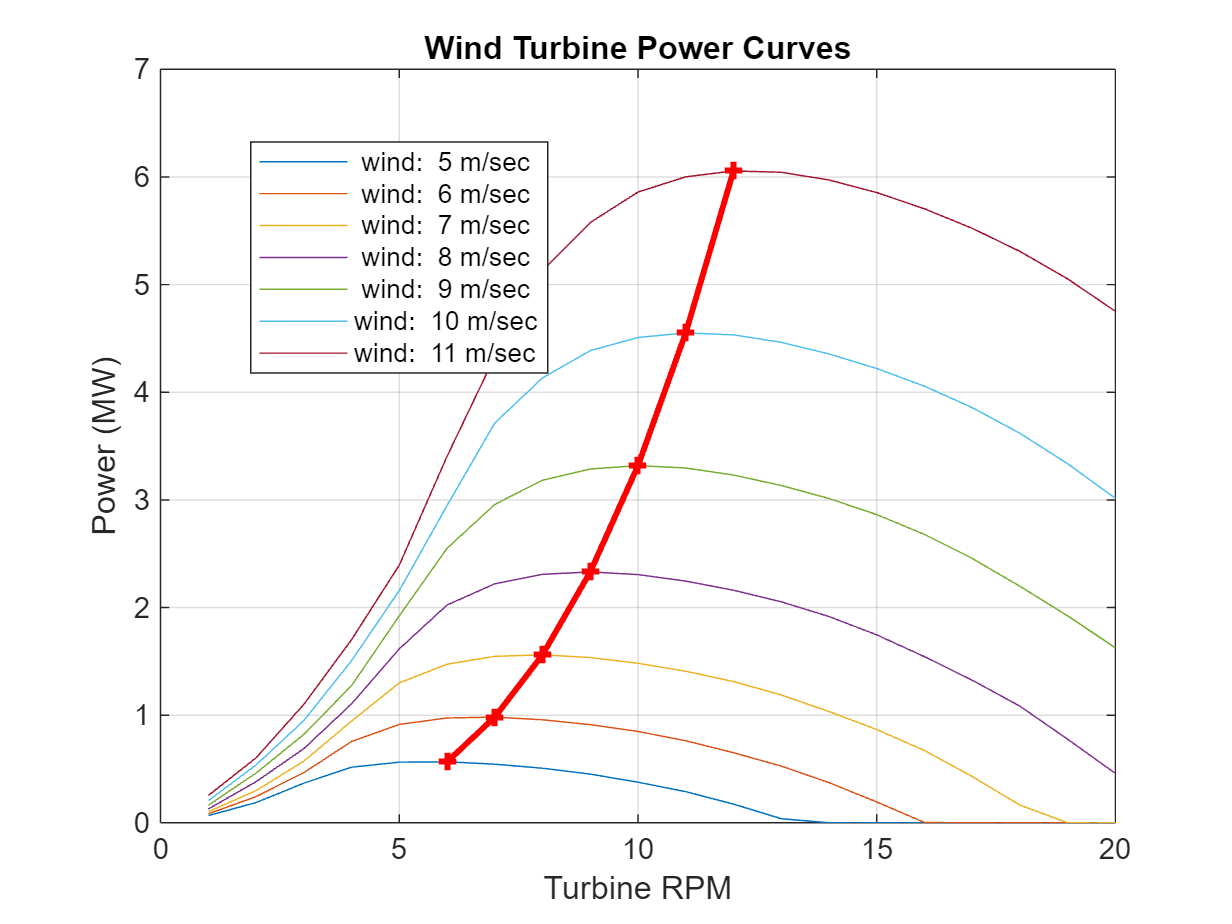

mdl='AdmittanceScanPRBS'; % Test model with IBR plant
open_system(mdl);% Loading the model

in=Simulink.SimulationInput(mdl); % Configure test model using simulation input
in=in.setBlockParameter('AdmittanceScanPRBS/Renewable Plant','Choice','Wind Farm'); % Configure renewable plant as Wind Farm
in=in.setBlockParameter('AdmittanceScanPRBS/Renewable Plant','nGFL','5');% Configure block parameters using simulation input
in=in.setBlockParameter('AdmittanceScanPRBS/Renewable Plant','nGFM','0');% Configure block parameters using simulation input
in=in.setVariable('scan.Vd',0.01);% Configure variable parameters using simulation input
in=in.setVariable('scan.start',1.5);% Configure variable parameters using simulation input
in=in.setVariable('scan.end',4.5);% Configure variable parameters using simulation input
in=in.setBlockParameter('AdmittanceScanPRBS/Grid','LabelModeActiveChoice','Voltage Source');% Configure block parameters using simulation input
in=in.setVariable('time.loadswitch',Tsim+1);% Configure variable parameters using simulation input
in=in.setVariable('loadstep1',1);% Configure variable parameters using simulation input
in=in.setVariable('loadstep2',1);% Configure variable parameters using simulation input
in=in.setModelParameter('StopTime',num2str(4.5));% Configure variable parameters using simulation input
data=sim(in);% Simulate model with injected disturbance

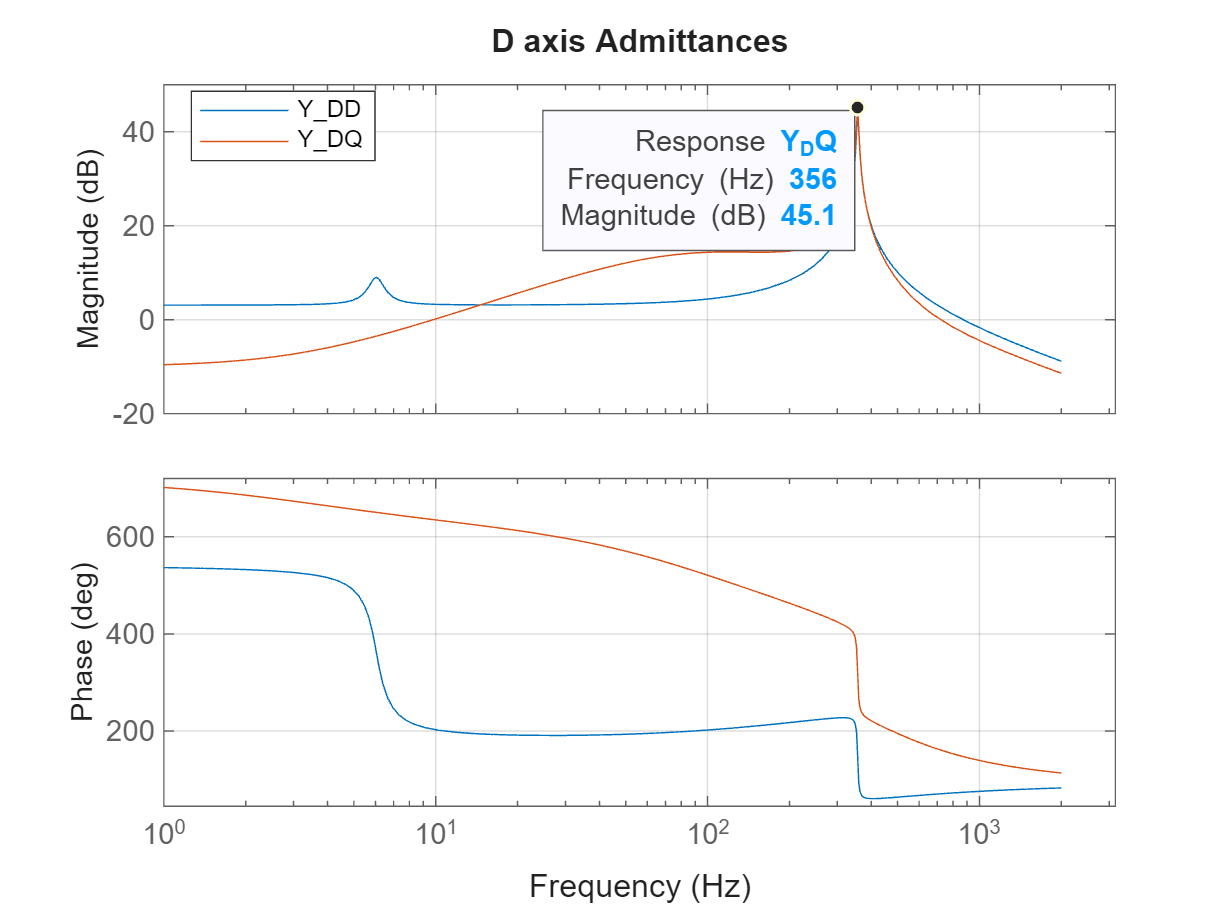

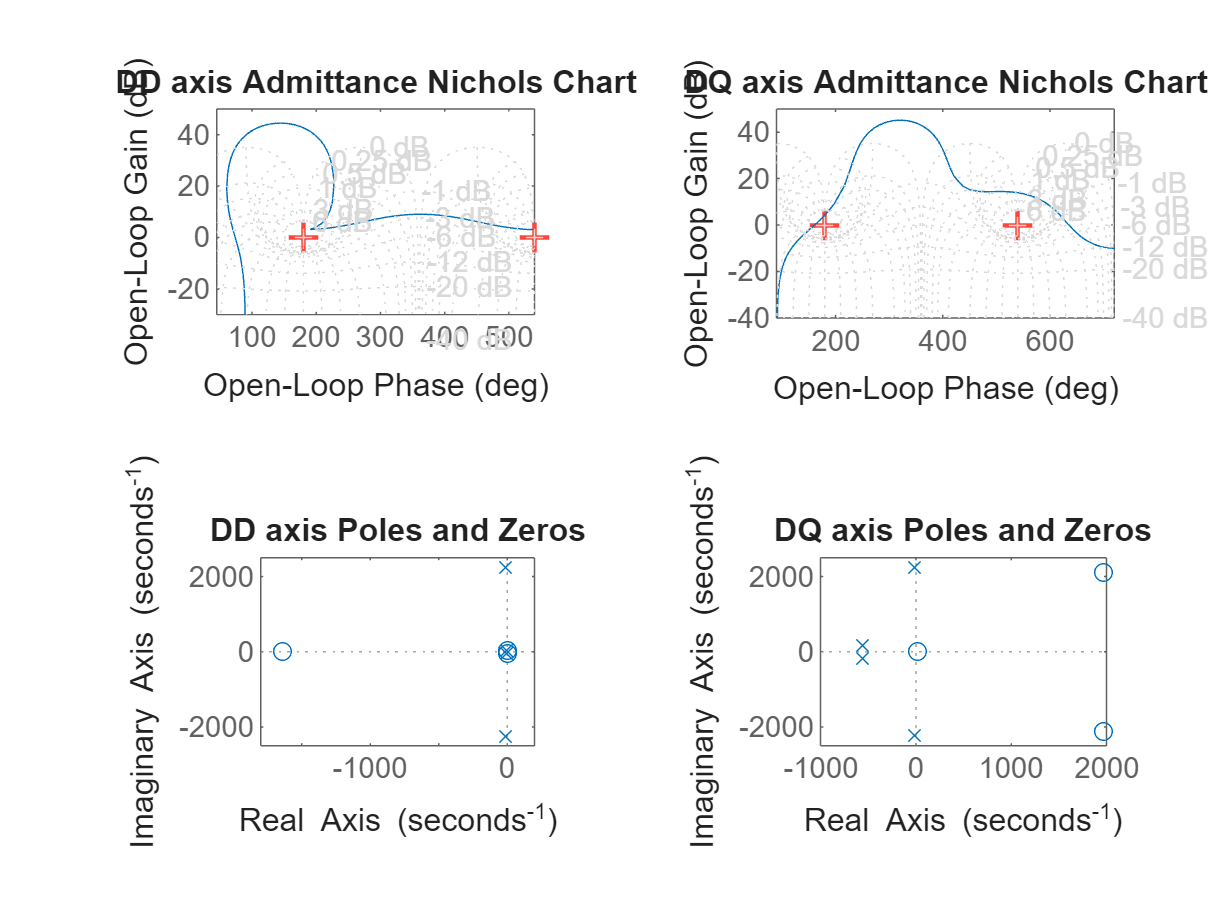

scan.Vd=0.01;
scan.Vq=0.0;
sys.case1d=admittancescanPRBS(scan.Vd,scan.Vq,0,scan.f,data.scan,modelorder,'Y');  % This function performs admittance scan along D axis

in=in.setVariable('scan.Vd',0.0);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vq',0.01);% Configure variable parameters using simulation input
data=sim(in);% Simulate model with injected disturbance

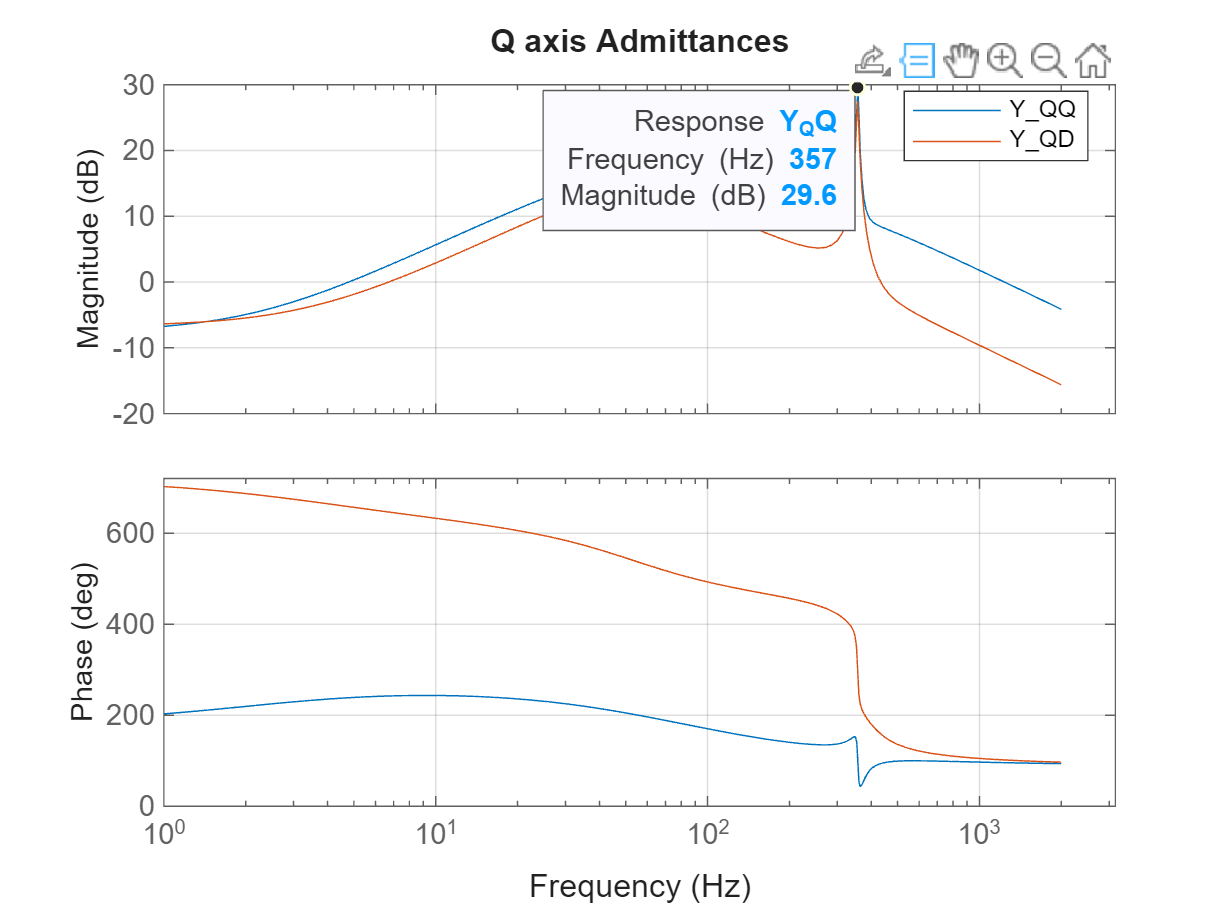

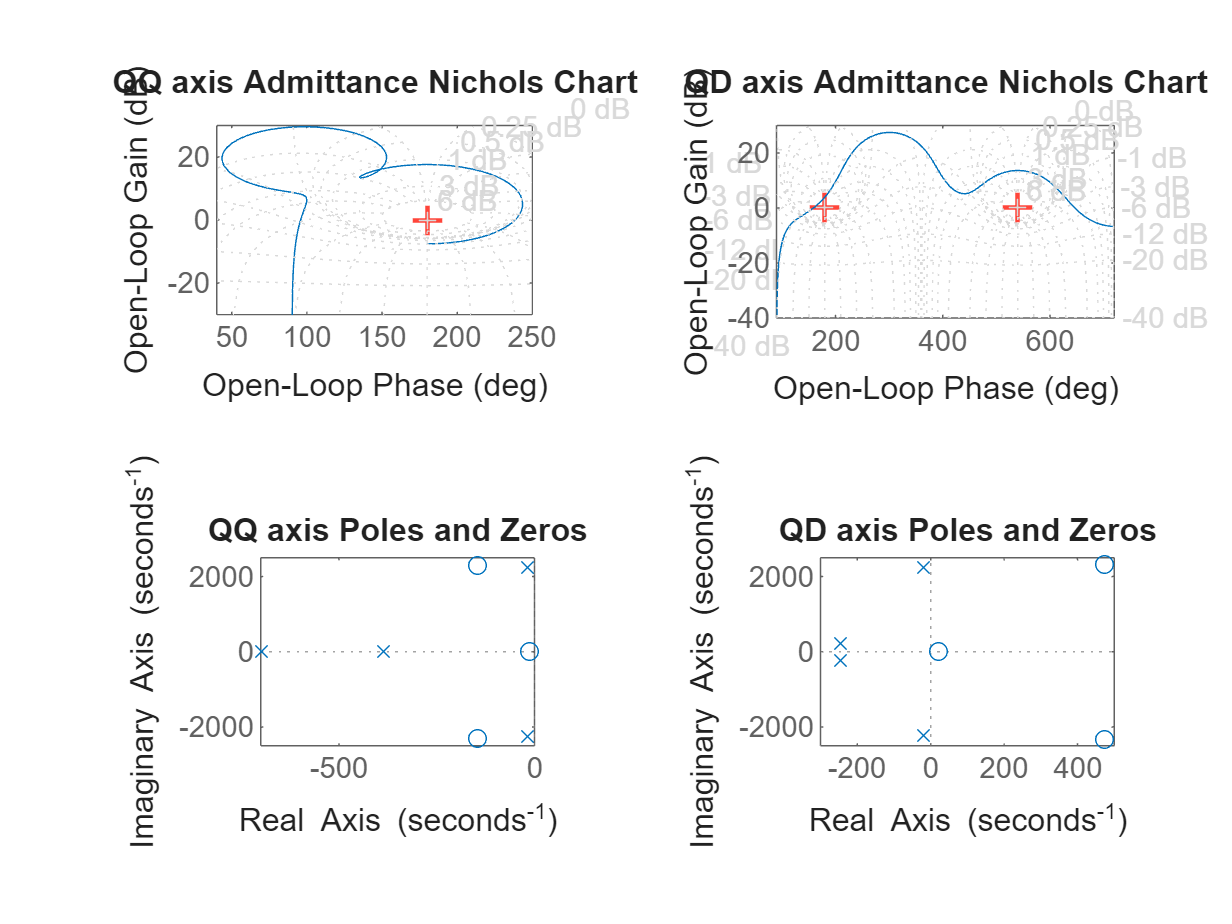

scan.Vq=0.01;
scan.Vd=0.0;
sys.case1q=admittancescanPRBS(scan.Vd,scan.Vq,0,scan.f,data.scan,modelorder,'Y');  % This function performs admittance scan along Q axis

%% Simulating a load switching event
in=in.setVariable('time.loadswitch',2.5);% Configure variable parameters using simulation input
in=in.setVariable('loadstep1',0);% Configure variable parameters using simulation input
in=in.setVariable('loadstep2',1);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vd',0.0);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vq',0.0);% Configure variable parameters using simulation input
data=sim(in); % Simulate model with load switching

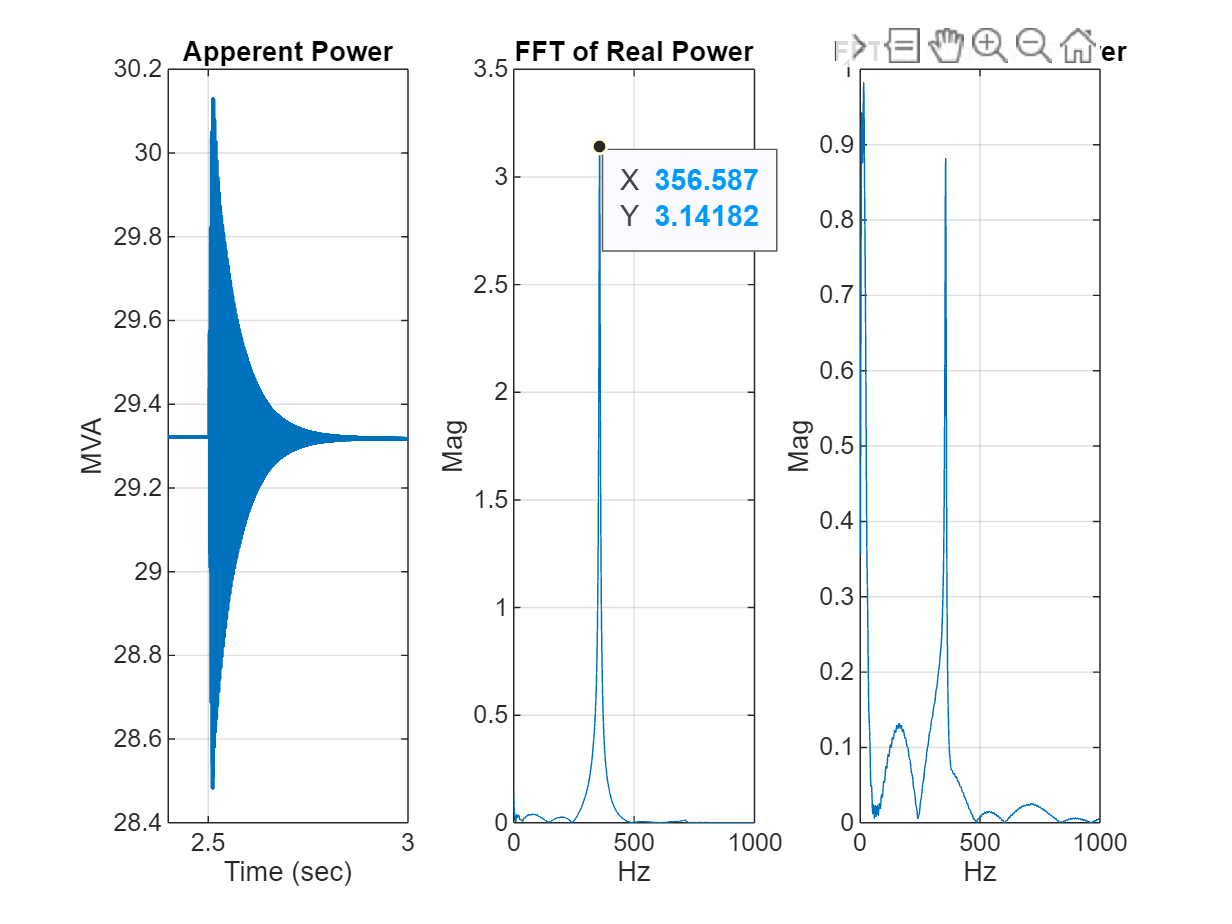

%%Performing FFT of power Waveform during load switching
fFTPower(scan,data,2.5)

This figure shows the active power output of the renewable plant during a step change of the load connected in the system. The fast Fourier transform (FFT) of the power waveform shows an oscillation around 432 Hz during the transient period, which confirms the presence of the mode seen in the above admittance spectrum.

#### Case 1.2 Wind Farm with 4 GFL and 1 GFM Wind generator and the Grid Modelled with Voltage Source

in=in.setBlockParameter('AdmittanceScanPRBS/Renewable Plant','nGFL','4');% Configure block parameters using simulation input
in=in.setBlockParameter('AdmittanceScanPRBS/Renewable Plant','nGFM','1');% Configure block parameters using simulation input
in=in.setVariable('scan.Vd',0.01);% Configure variable parameters using simulation input
in=in.setVariable('scan.start',1.5);% Configure variable parameters using simulation input
in=in.setVariable('scan.end',4.5);% Configure variable parameters using simulation input
in=in.setBlockParameter('AdmittanceScanPRBS/Grid','LabelModeActiveChoice','Voltage Source');% Configure block parameters using simulation input
in=in.setVariable('time.loadswitch',Tsim+1);% Configure variable parameters using simulation input
in=in.setVariable('loadstep1',0);% Configure variable parameters using simulation input
in=in.setVariable('loadstep2',0);% Configure variable parameters using simulation input
data=sim(in);% Simulate model with injected disturbance

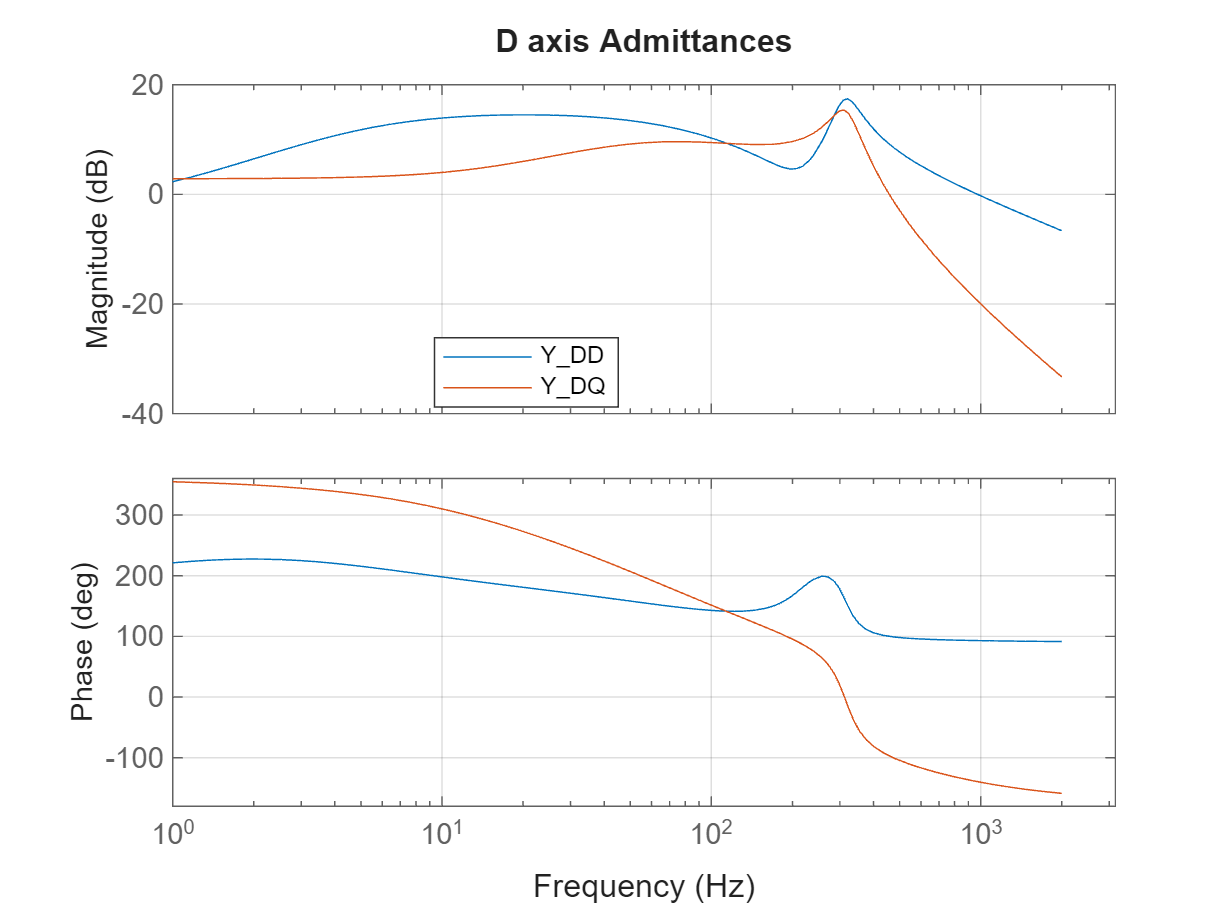

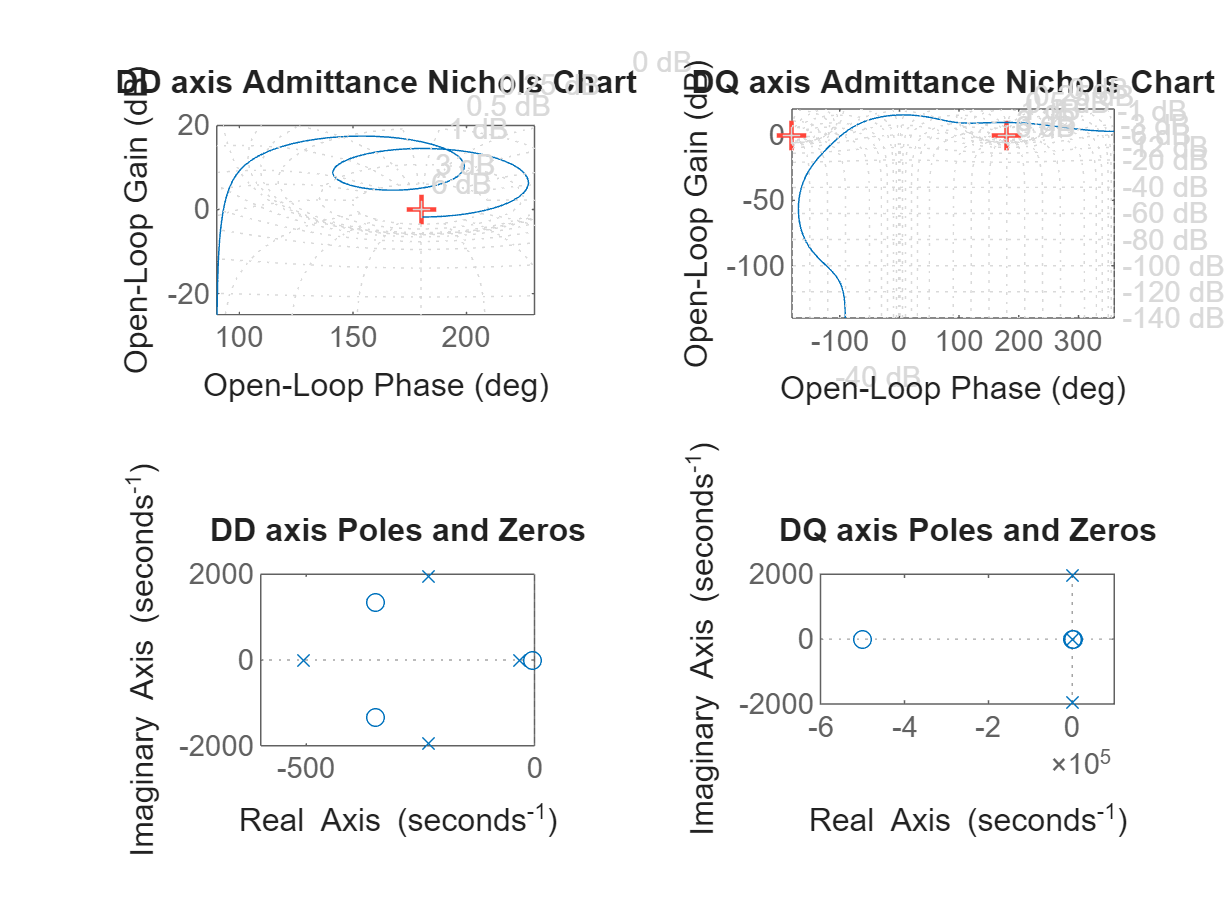

% Perform admittance scan
scan.Vq=0.0;
scan.Vd=0.01;
sys.case12d=admittancescanPRBS(scan.Vd,scan.Vq,0,scan.f,data.scan,modelorder,'Y'); % This function performs admittance scan along D axis

in=in.setVariable('scan.Vd',0.0);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vq',0.01);% Configure variable parameters using simulation input
data=sim(in);% Simulate model with injected disturbance

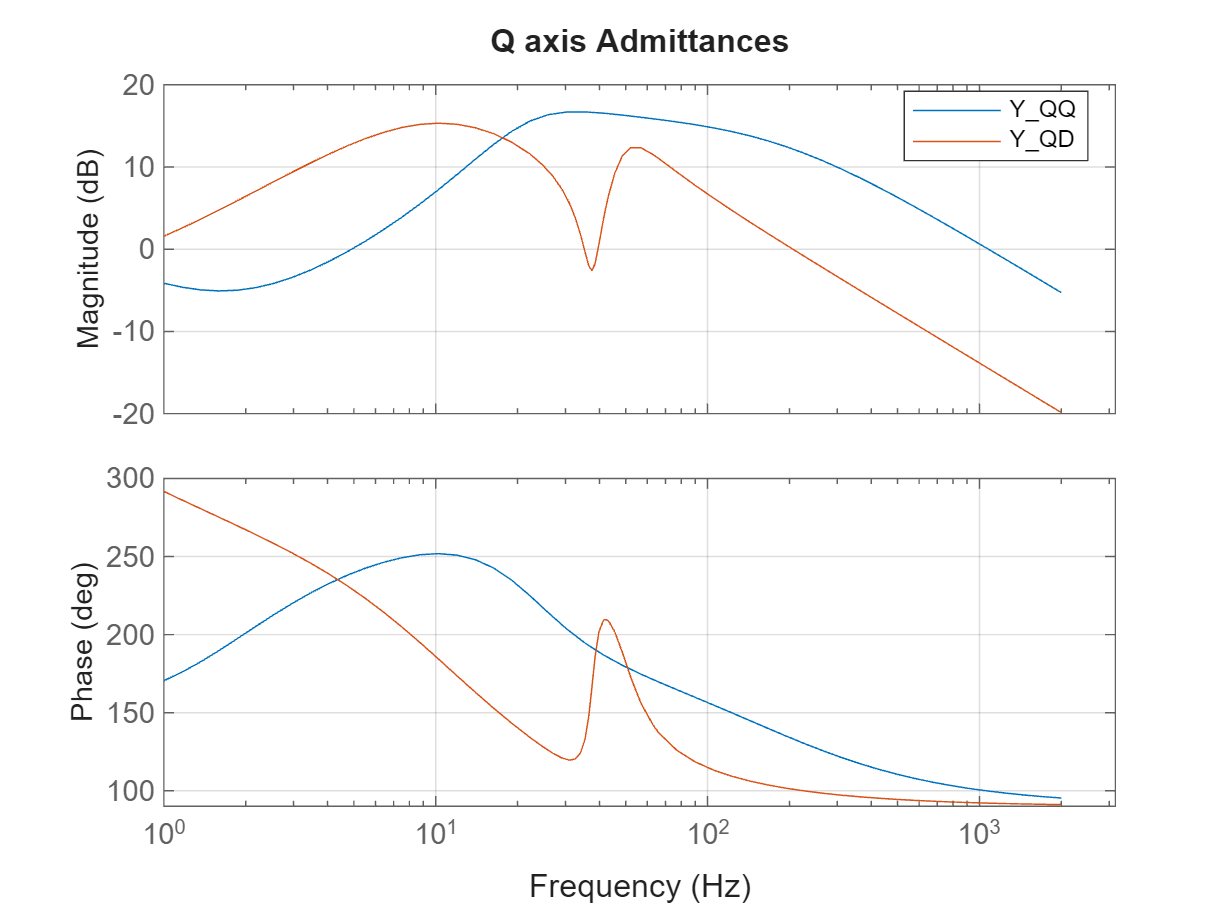

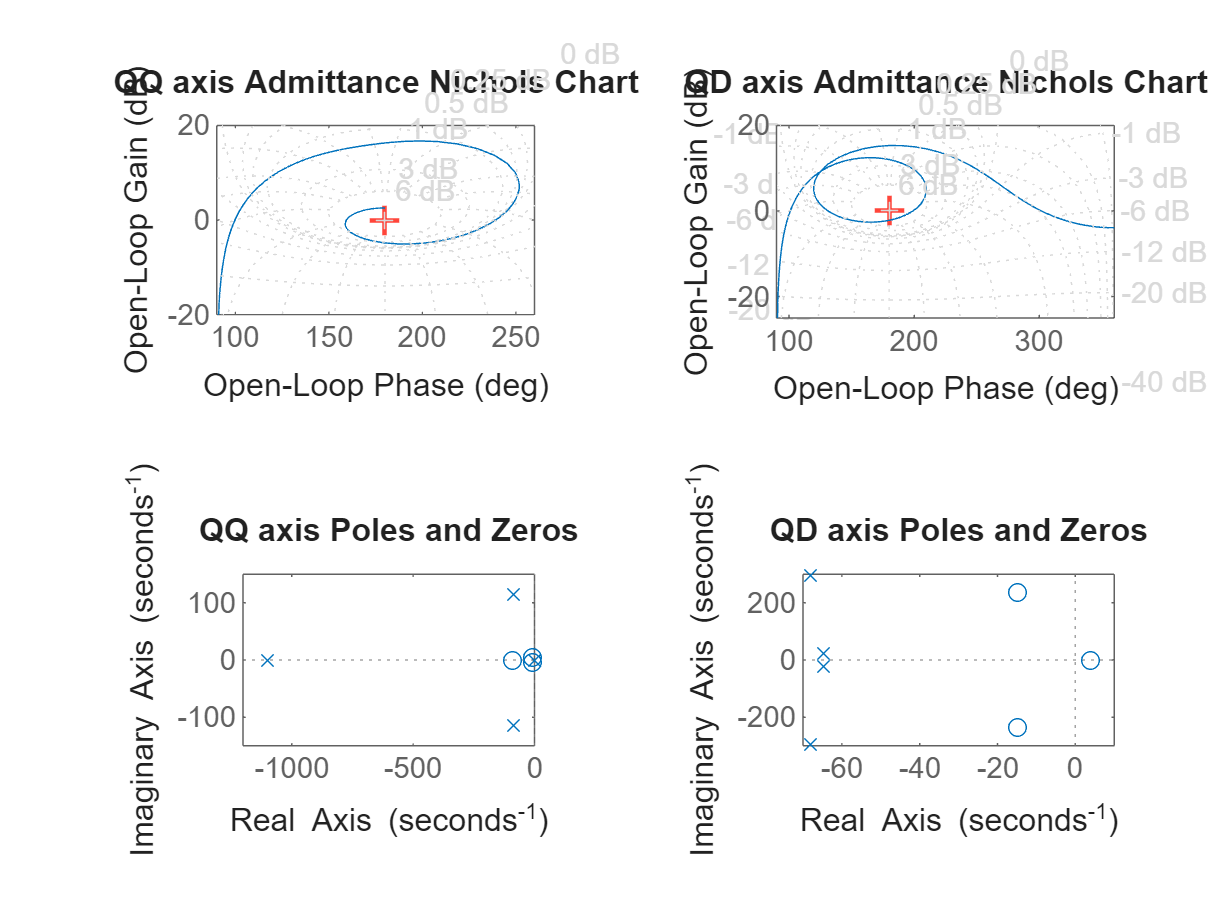

scan.Vq=0.01;
scan.Vd=0.0;
sys.case12q=admittancescanPRBS(scan.Vd,scan.Vq,0,scan.f,data.scan,modelorder,'Y');  % This function performs admittance scan along Q axis

in=in.setVariable('time.loadswitch',2.5);% Configure variable parameters using simulation input
in=in.setVariable('loadstep1',0);% Configure variable parameters using simulation input
in=in.setVariable('loadstep2',1);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vd',0.0);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vq',0.0);% Configure variable parameters using simulation input
data=sim(in);% Simulate model with load switching

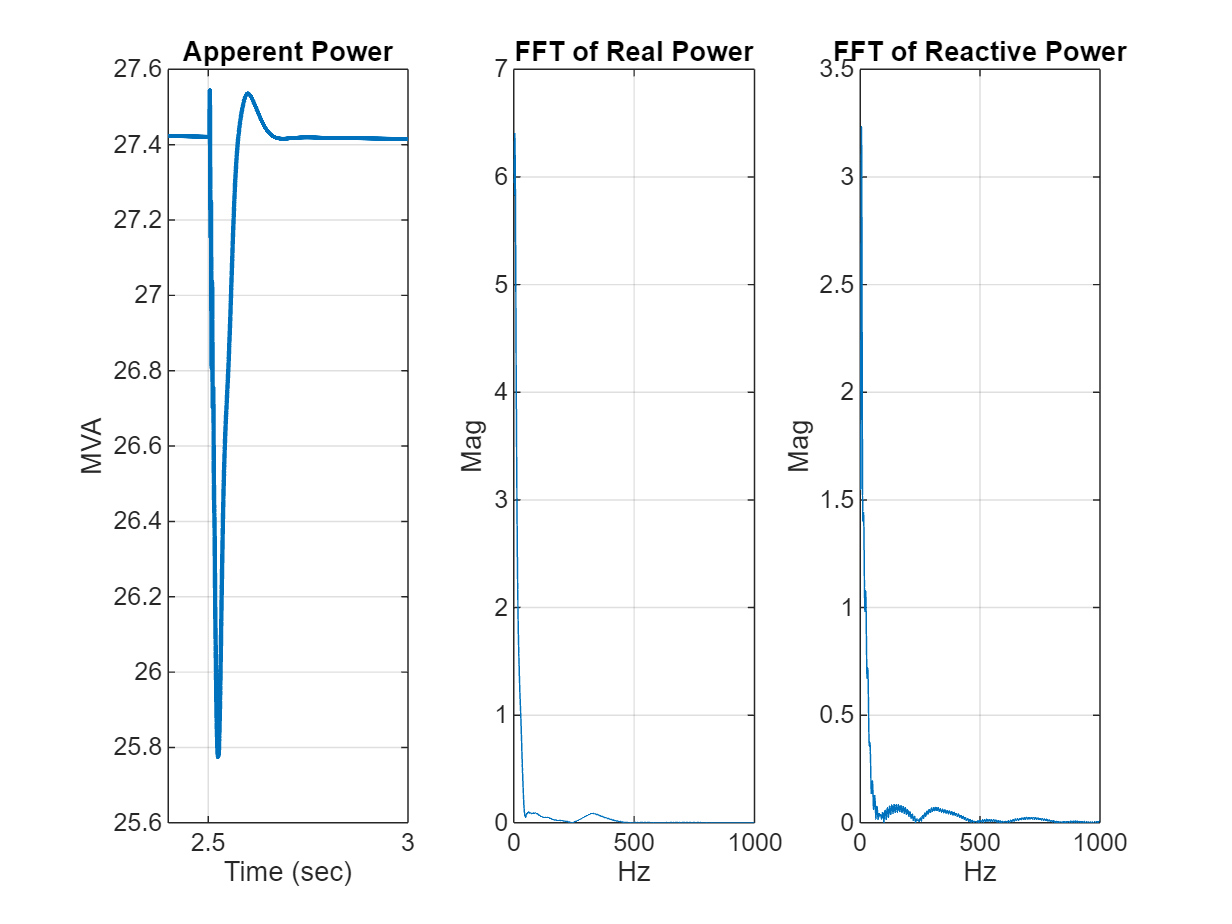

%%Performing FFT of power Waveform during load switching
fFTPower(scan,data,2.5)

With the GFM controller for one of the wind generators, you can see that the oscillations in power outputs of the renewable plant is reduced significantly. Thus, the sharpness of the resonance peaks have also reduced in the admittance spectrum. This shows that the GFM controller has improved the oscillatory stability of the system.

### Solar Plant and BESS Integration Model

In this case the renewable plant is configured as a PV plant with a BESS unit , which is connected to the medium voltage network through a 4.16 kV/24.9 kV transformer. The PV plant inverters operate at their MPP by using a PLL-based GFL control.

You can operate the BESS inverter as a GFM unit, using a virtual synchronous-machine-based GFM controller or as a GFL unit with voltage and frequency supporting functions.

#### Case 2.1 Solar Plant with BESS as GFL and Grid Modelled with Voltage Source

in=in.setBlockParameter('AdmittanceScanPRBS/Renewable Plant','Choice','PV Plant'); % Configure renewable plant as Solar Plant with BESS
in=in.setBlockParameter('AdmittanceScanPRBS/Renewable Plant','LabelModeActiveChoice1','BESSGridSupporting');% Configure block parameters using simulation input
in=in.setBlockParameter('AdmittanceScanPRBS/Grid','LabelModeActiveChoice','Voltage Source');% Configure block parameters using simulation input
in=in.setVariable('scan.Vd',0.02);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vq',0.0);% Configure variable parameters using simulation input
in=in.setVariable('scan.start',1.5);% Configure variable parameters using simulation input
in=in.setVariable('scan.end',4.5);% Configure variable parameters using simulation input
in=in.setVariable('time.loadswitch',Tsim+10);% Configure variable parameters using simulation input
in=in.setVariable('loadstep1',0);% Configure variable parameters using simulation input
in=in.setVariable('loadstep2',0);% Configure variable parameters using simulation input
in=in.setModelParameter('StopTime',num2str(5));% Configure variable parameters using simulation input

data=sim(in);% Simulate model with injected disturbance

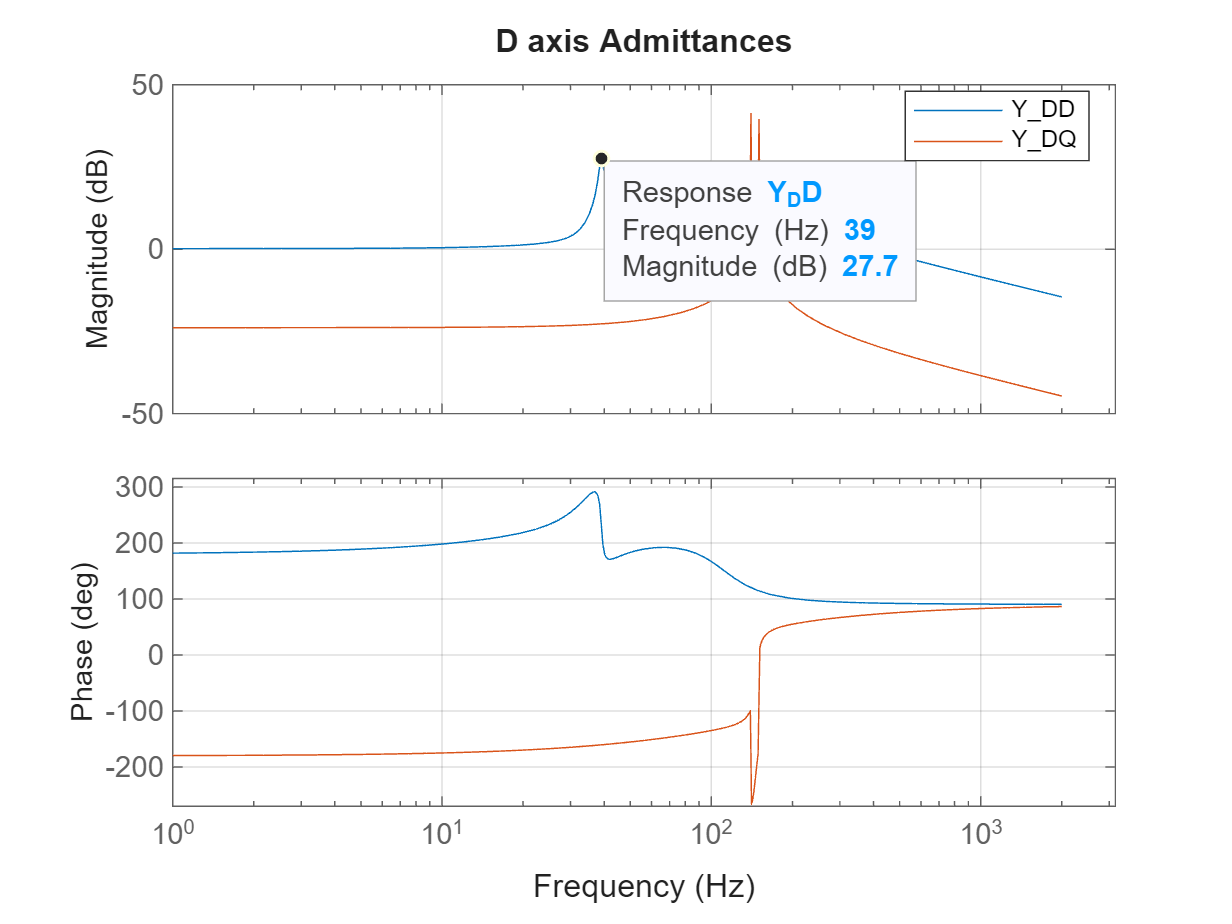

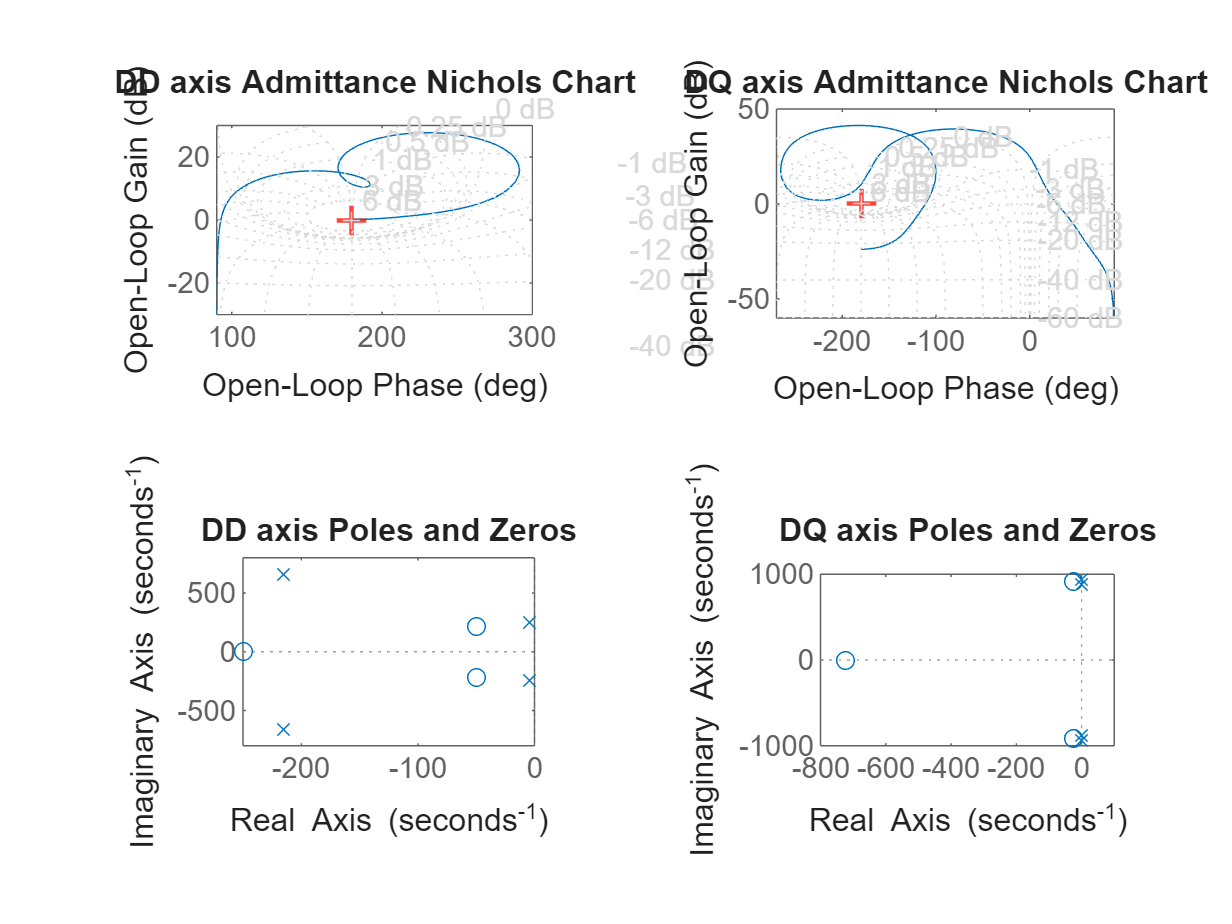

% Perform admittance scan
scan.Vd=0.02;
scan.Vq=0.0;
sys.case2d=admittancescanPRBS(scan.Vd,scan.Vq,0,scan.f,data.scan,modelorder,'Y');

in=in.setVariable('scan.Vd',0.0);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vq',0.01);% Configure variable parameters using simulation input
data=sim(in);% Simulate model with injected disturbance

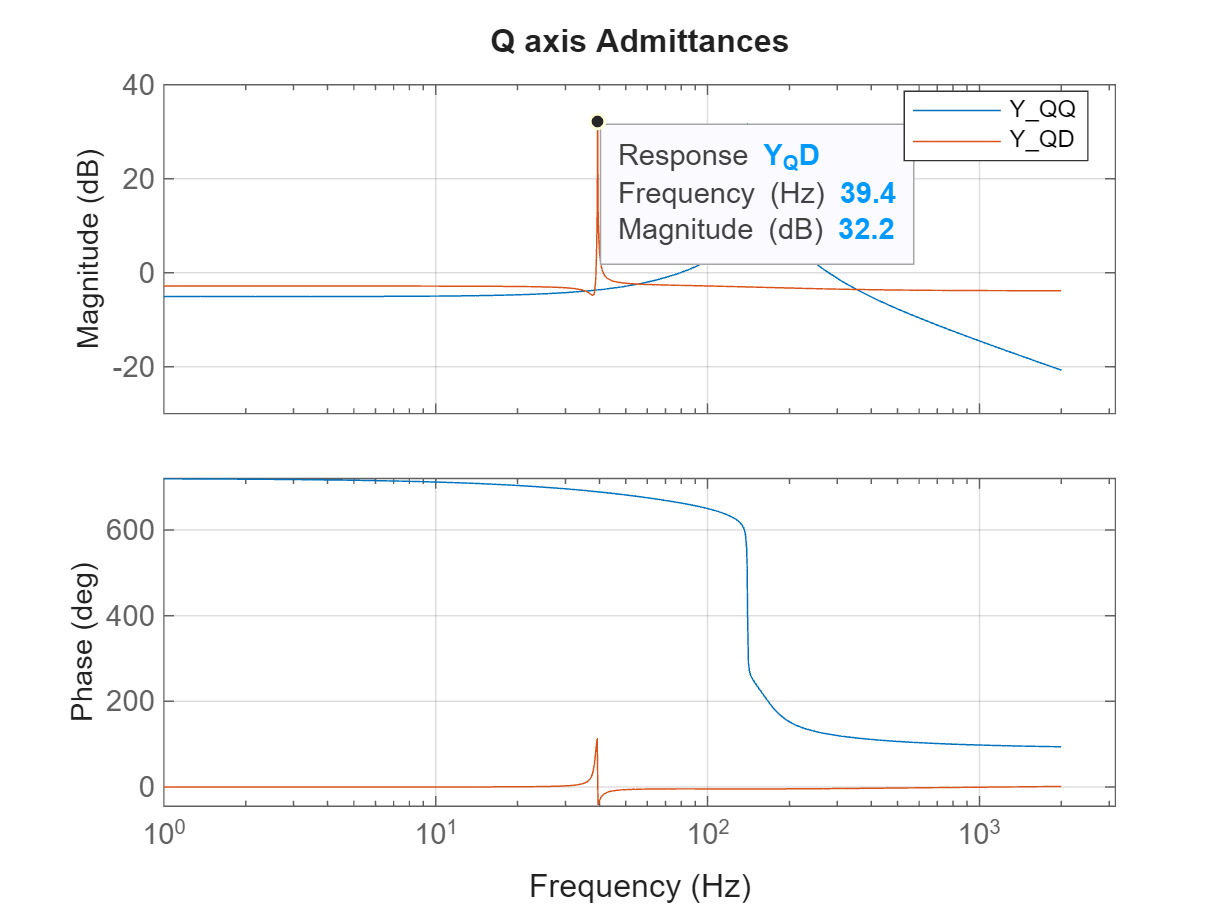

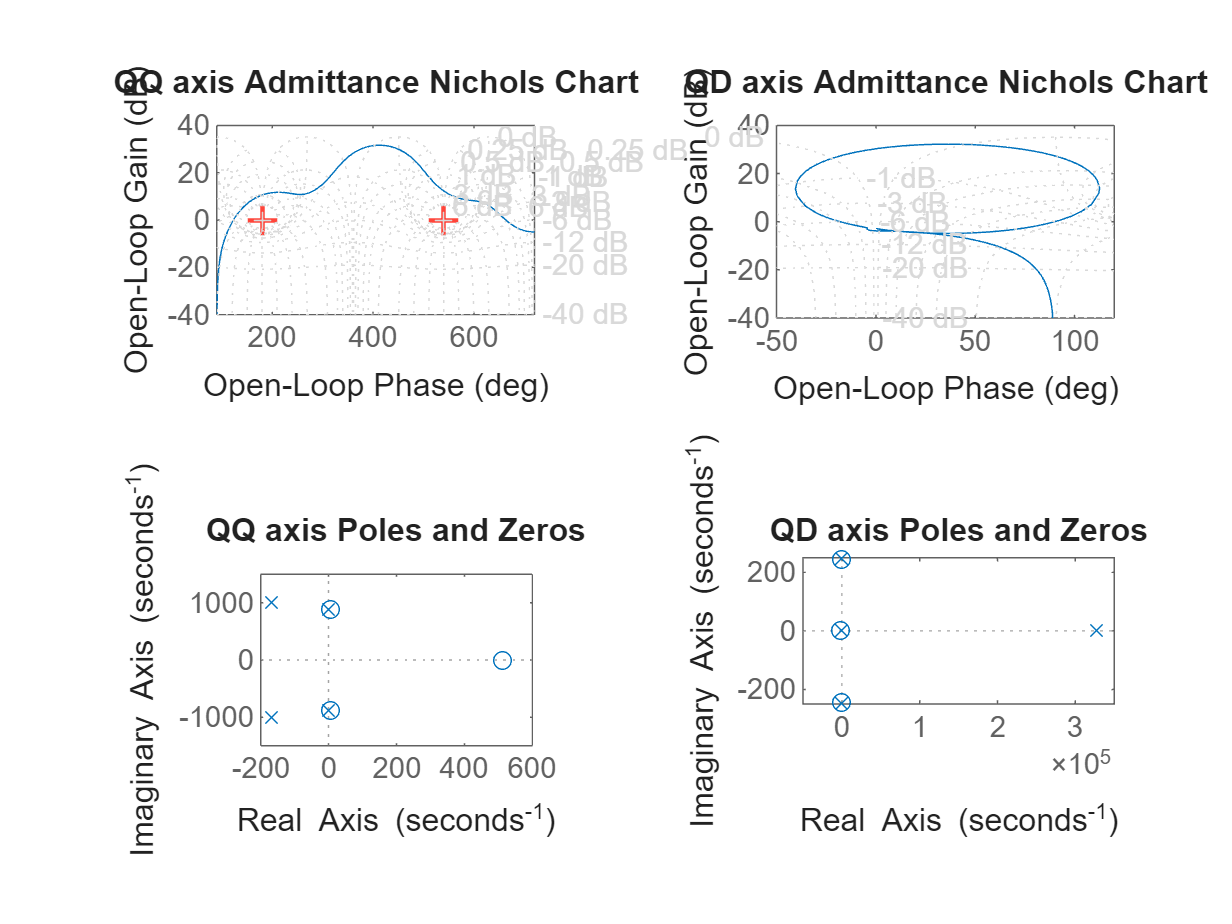

scan.Vq=0.01;
scan.Vd=0.0;
sys.case2q=admittancescanPRBS(scan.Vd,scan.Vq,0,scan.f,data.scan,modelorder,'Y');  % This function performs admittance scan along Q axis

in=in.setVariable('time.loadswitch',2.5);% Configure variable parameters using simulation input
in=in.setVariable('loadstep1',0);% Configure variable parameters using simulation input
in=in.setVariable('loadstep2',1);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vd',0.0);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vq',0.0);% Configure variable parameters using simulation input
data=sim(in);% Simulate model with load switching

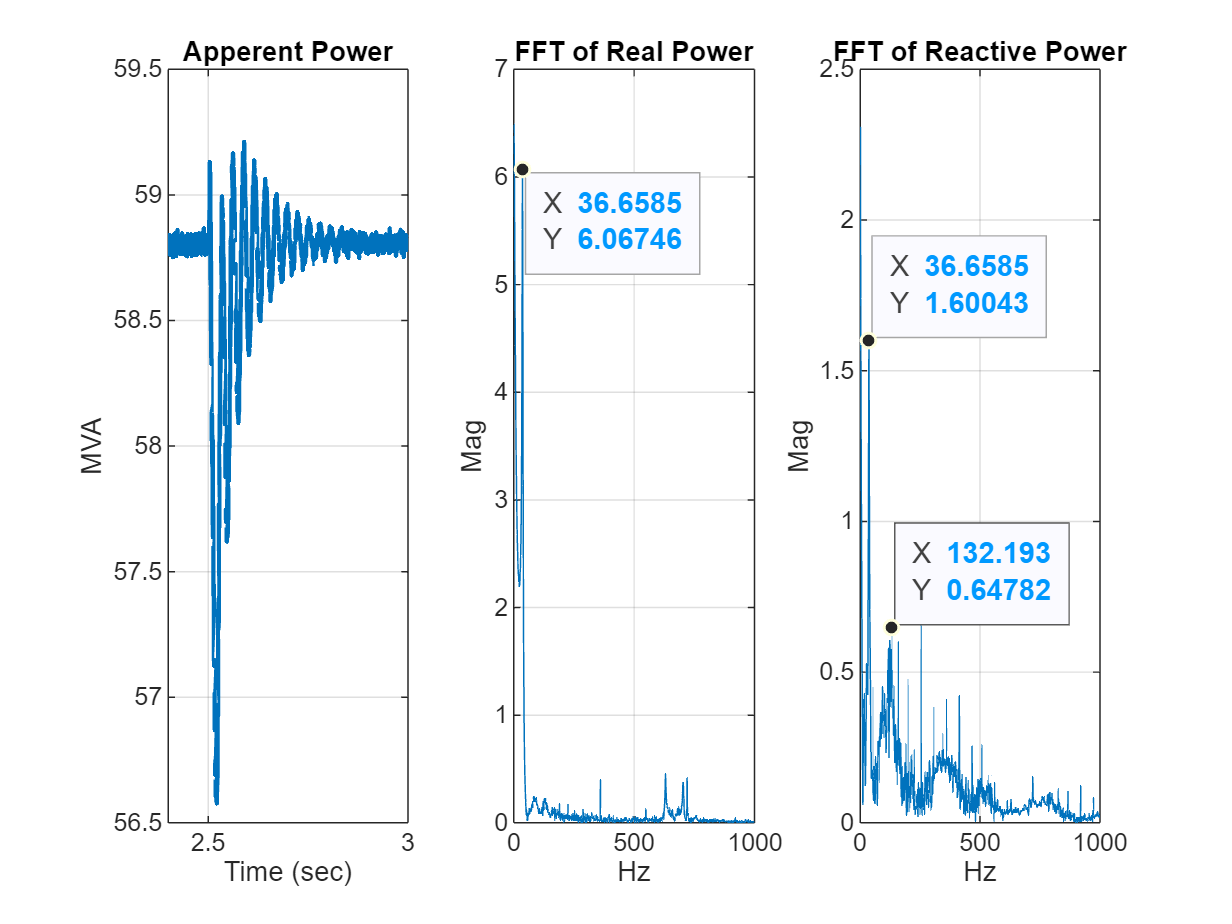

%%Performing FFT of power Waveform during load switching
fFTPower(scan,data,2.5)

This figure shows the active power output of the renewable plant during a step change of the load connected in the system. The FFT analysis of the real and reactive power shows oscillations  around 36 Hz, 130 Hz during the transient period, which confirms the presence of the mode seen in the above admittance spectrum.

#### Case 2.2 Solar Plant with BESS as GFM VSM and Grid Modelled with Voltage Source

in=in.setBlockParameter('AdmittanceScanPRBS/Renewable Plant','LabelModeActiveChoice1','BESSVSMControl');% Configure block parameters using simulation input
in=in.setBlockParameter('AdmittanceScanPRBS/Grid','LabelModeActiveChoice','Voltage Source');% Configure block parameters using simulation input
in=in.setVariable('scan.Vd',0.01);% Configure variable parameters using simulation input
in=in.setVariable('scan.start',2);% Configure variable parameters using simulation input
in=in.setVariable('scan.end',6.5);% Configure variable parameters using simulation input
in=in.setVariable('time.loadswitch',Tsim+10);% Configure variable parameters using simulation input
in=in.setVariable('loadstep1',0);% Configure variable parameters using simulation input
in=in.setVariable('loadstep2',0);% Configure variable parameters using simulation input
in=in.setModelParameter('StopTime',num2str(6.5));
data=sim(in);% Simulate model with injected disturbance

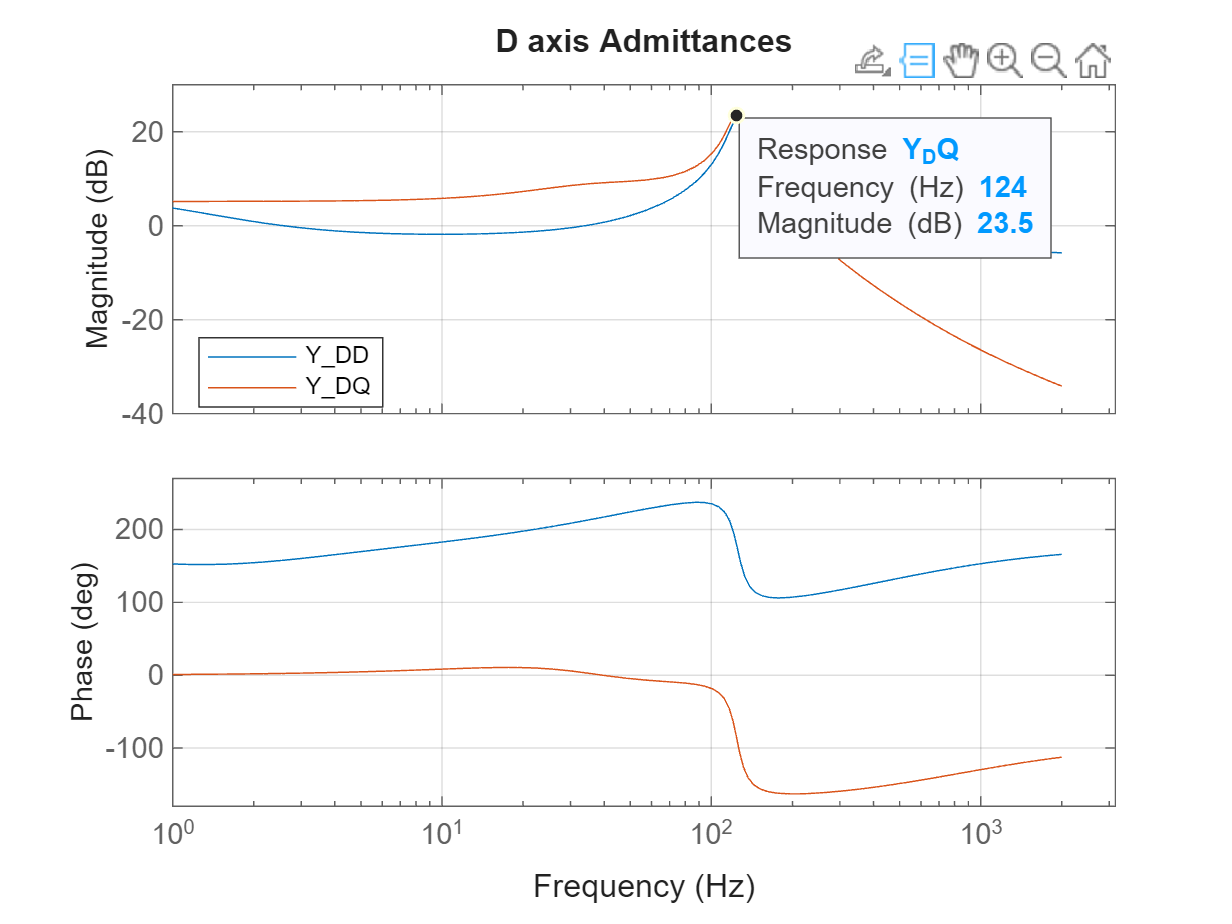

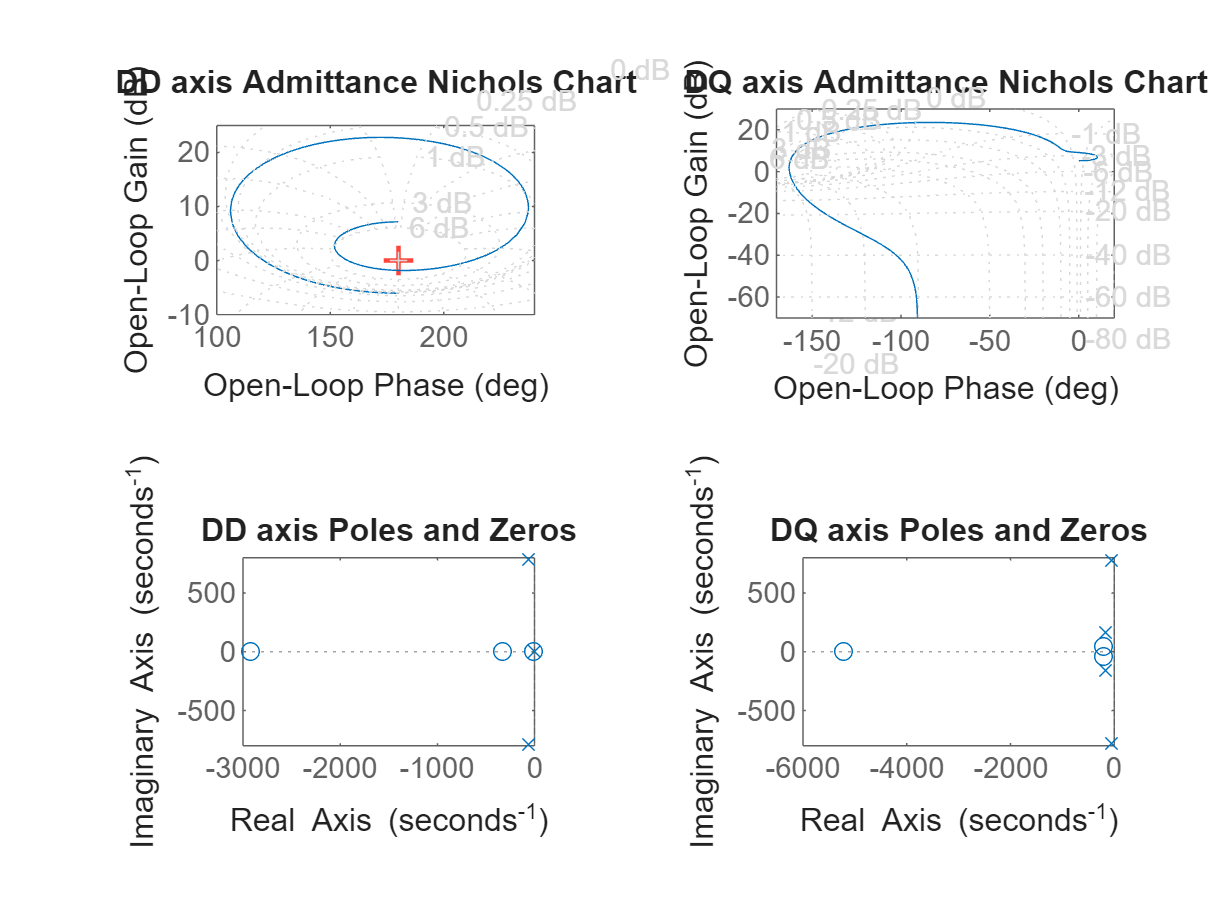

% Perform admittance scan
scan.Vd=0.01;
scan.Vq=0.0;
sys.case21d=admittancescanPRBS(scan.Vd,scan.Vq,0,scan.f,data.scan,modelorder,'Y');

in=in.setVariable('scan.Vd',0.0);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vq',0.01);% Configure variable parameters using simulation input
data=sim(in);% Simulate model with injected disturbance

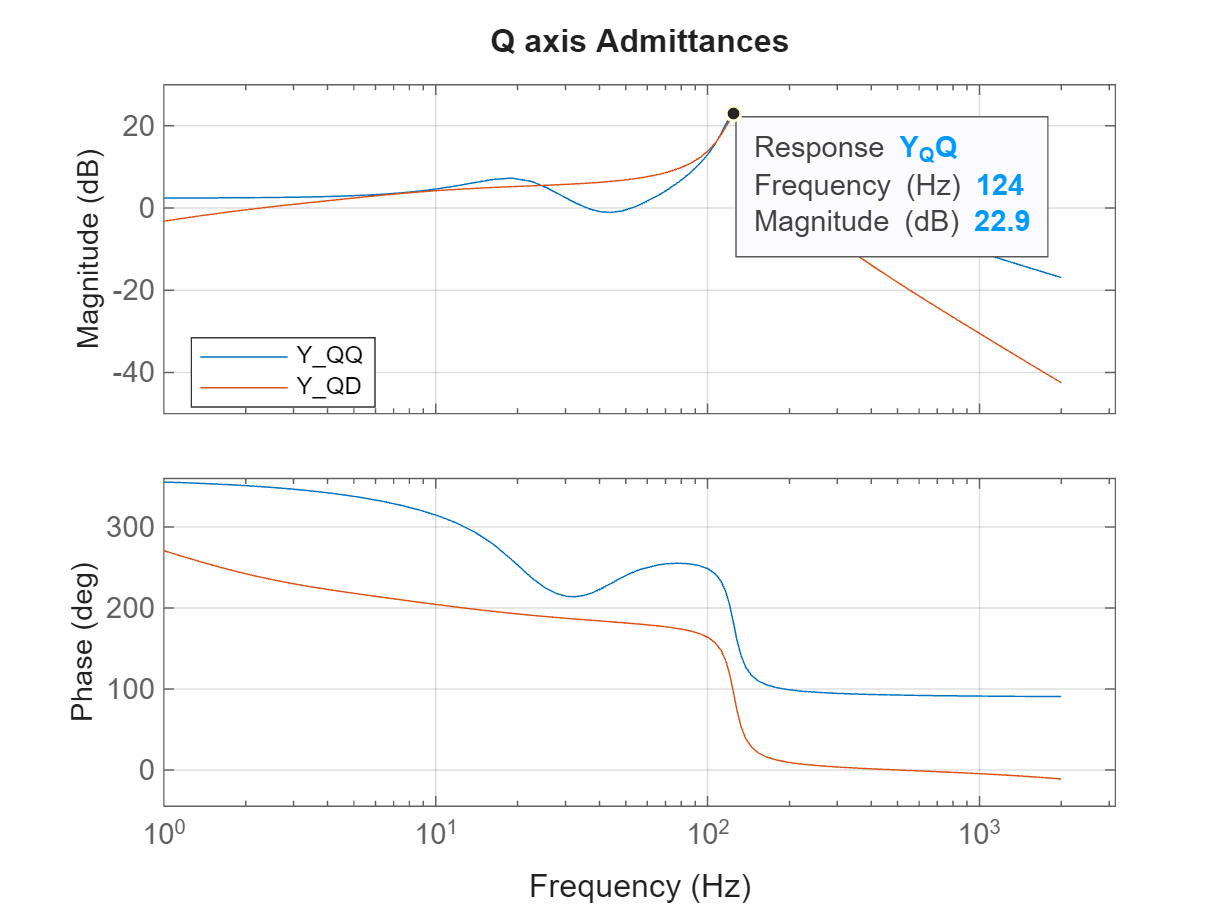

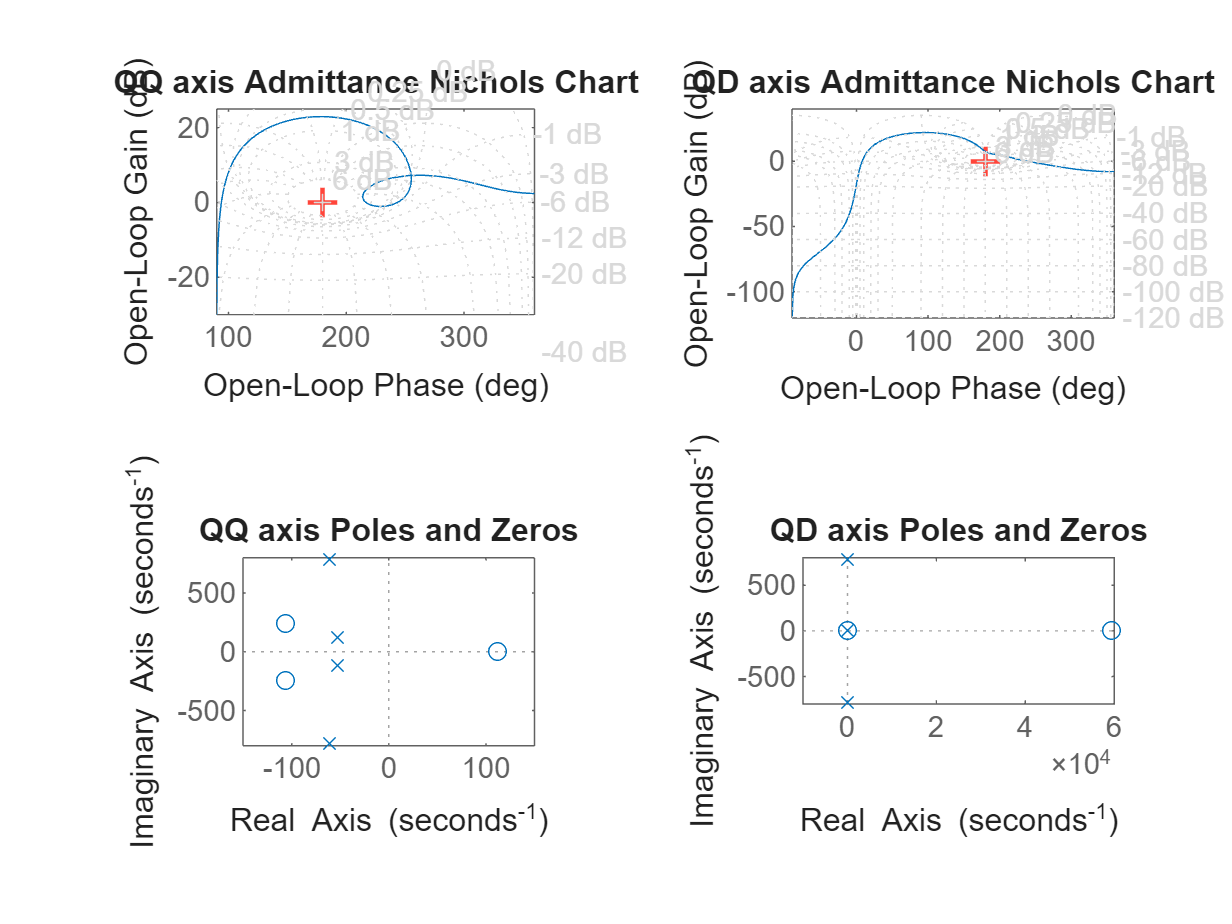

scan.Vq=0.01;
scan.Vd=0.0;
sys.case21q=admittancescanPRBS(scan.Vd,scan.Vq,0,scan.f,data.scan,modelorder,'Y'); % This function performs admittance scan along Q axis

in=in.setVariable('time.loadswitch',2.5);% Configure variable parameters using simulation input
in=in.setVariable('loadstep1',0);% Configure variable parameters using simulation input
in=in.setVariable('loadstep2',1);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vd',0.0);% Configure variable parameters using simulation input
in=in.setVariable('scan.Vq',0.0);% Configure variable parameters using simulation input
data=sim(in);% Simulate model with load switching

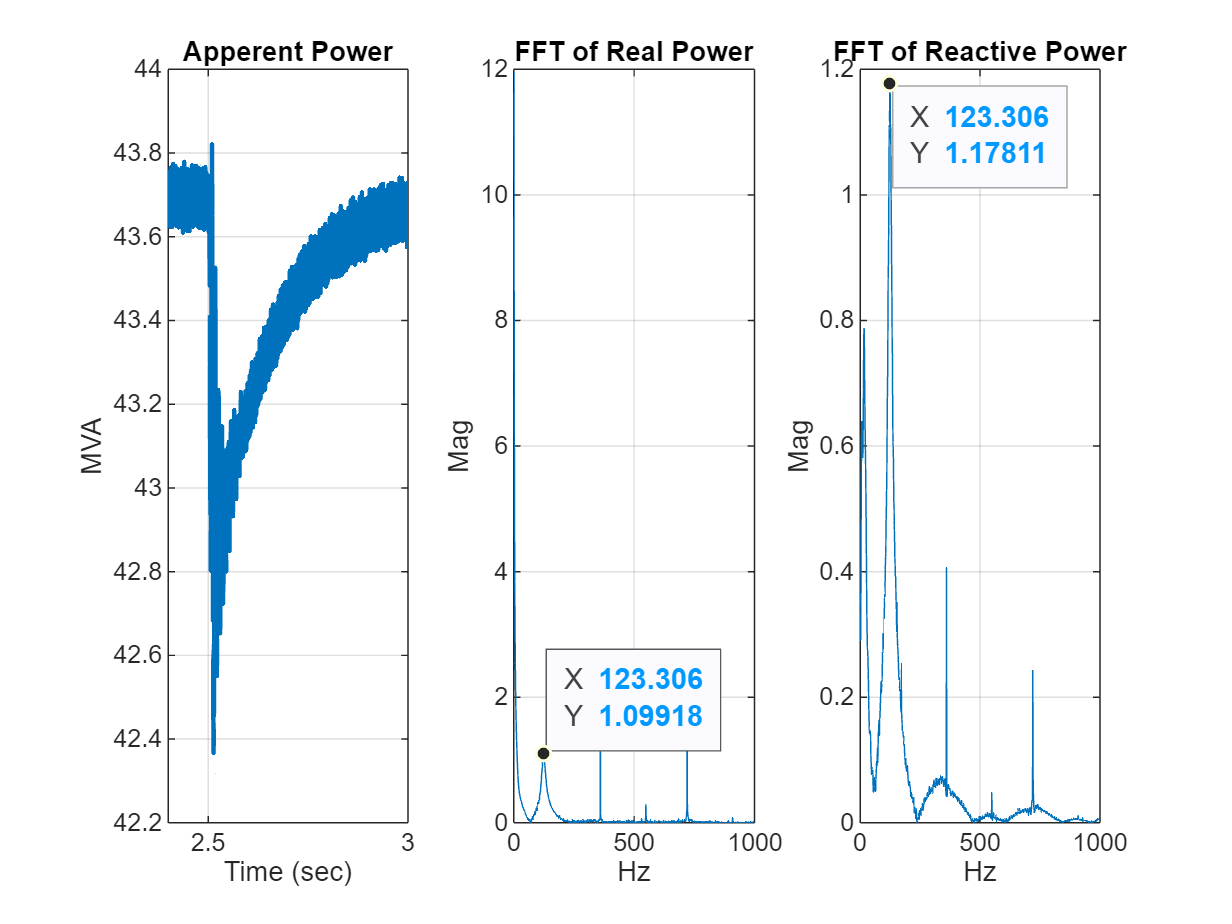

%%Performing FFT of power Waveform during load switching
fFTPower(scan,data,2.5)

Using a GFM BESS controller instead of GFL controller, leads to less sharper resonance peaks at around 124 Hz. This shows that the GFM converter has improved the damping of the overall system.

### Summary

This project provides an admittance scan block which you can use to detect the oscillatory unstable modes in a renewable integrated power system. Use this Admittance Scan block to inject PRBS voltage disturbance at the POI and log the perturbed currents and voltages. Then, after obtaining the perturbed measurements, you can use the `admittancescanPRBS(Vd,Vq,Vdc,f,data,modelorder) `function to obtain the admittance spectrum of the system at the POI. 

## References

[1] Y. Gu, Y. Li, Y. Zhu and T. C. Green, "Impedance-Based Whole-System Modeling for a Composite Grid via Embedding of Frame Dynamics," in *IEEE Transactions on Power Systems*, vol. 36, no. 1, pp. 336-345, Jan. 2021.

[2]  A. Riccobono, M. Mirz and A. Monti, "Noninvasive Online Parametric Identification of Three-Phase AC Power Impedances to Assess the Stability of Grid-Tied Power Electronic Inverters in LV Networks," in *IEEE Journal of Emerging and Selected Topics in Power Electronics*, vol. 6, no. 2, pp. 629-647, June 2018.